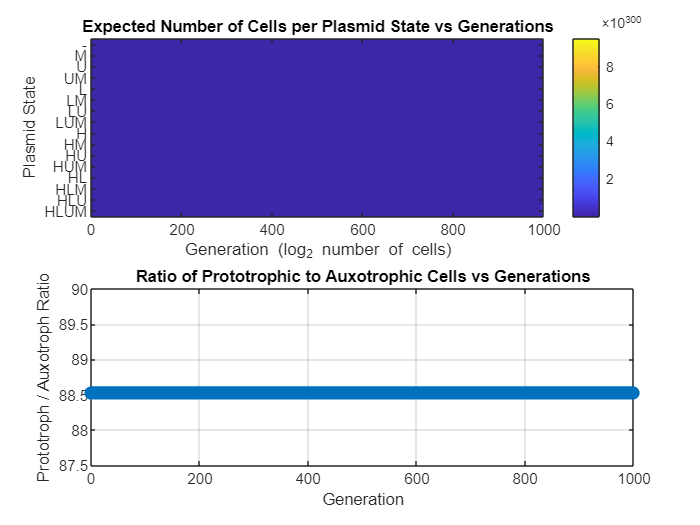

% MATLAB: Bernoulli model for exponentially growing cell numbers

p_s = 0.03; % plasmid-loss probability
num_generations = 1000; % total generations
num_cells = 2.^(0:num_generations); % exponential cell number

% Define plasmid states explicitly
plasmid_labels = {'-', 'M', 'U', 'UM', 'L', 'LM', 'LU', 'LUM', ...
                  'H', 'HM', 'HU', 'HUM', 'HL', 'HLM', 'HLU', 'HLUM'};

% Compute probabilities for each of 16 plasmid states
plasmid_states = dec2bin(0:15) - '0'; % binary representation
state_probs = zeros(1,16);

for i = 1:16
    state = plasmid_states(i,:);
    num_retained = sum(state);
    num_lost = 4 - num_retained;
    state_probs(i) = (p_s^num_lost)*((1 - p_s)^num_retained);
end

% Evaluate distribution across generations
distribution = zeros(num_generations+1, 16);
for gen = 0:num_generations
    distribution(gen+1,:) = num_cells(gen+1) * state_ probs;
end

% Determine prototroph (state HLUM) vs auxotroph ratio
prototroph_counts = distribution(:,16);
auxotroph_counts = sum(distribution(:,1:15),2);
ratio_prototroph_auxotroph = (prototroph_counts ./ (auxotroph_counts+prototroph_counts))*100;

% Plot distribution as cell numbers increase exponentially
figure;
subplot(2,1,1);
imagesc(0:num_generations, 1:16, distribution');
colorbar;
xlabel('Generation (log_2 number of cells)');
ylabel('Plasmid State');
title('Expected Number of Cells per Plasmid State vs Generations');
set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);

% Plot ratio of prototroph vs auxotroph over generations
subplot(2,1,2);
plot(0:num_generations, ratio_prototroph_auxotroph, '-o','LineWidth',2);
grid on;
xlabel('Generation');
ylabel('Prototroph / Auxotroph Ratio');
title('Ratio of Prototrophic to Auxotrophic Cells vs Generations');


% Final generation state distribution
disp('Final generation expected counts:');

Final generation expected counts:


for idx = 1:16
    fprintf('State %s: %.0f cells\n', plasmid_labels{idx}, distribution(end,idx));
end

State -: 8679219718208763885877682522938802349933239132263272479246690477479633528414140912262515500384546984428098588497527723054913628228916850829537232739225104757370593186676211719003684955296053913381684262431733413218188494921864836847667198958632960269063396939496478949556000948338579637505359872 cells
State M: 280628104222083356567347466041677386832844054758727482538244300336409808533397599726342388627804127245237070245882441444294397720899612064834896126157151427168630496216235522198728763297452411029624267586502815804411232390790866829633723725326446297089818997288075261922412999652140648694183624704 cells
State U: 280628104222083356567347466041677386832844054758727482538244300336409808533397599726342388627804127245237070245882441444294397720899612064834896126157151427168630496216235522198728763297452411029624267586502815804411232390790866829633723725326446297089818997288075261922412999652140648694183624704 cells
State UM: 90736420365140294850194932781931251645527891006277635